# Identificazione in frequenza in anello chiuso, con segnale eccitante sulla coppia

Motivazione:

- L'identificazione in anello aperto non consente di limitare l'andamento del sistema, causando possibili urti o il raggiungimento dei limiti del sistema

Obiettivi:

- analizzare le differenza fra la stima in anello aperto e anello chiuso al variare delle frequenza

- analizzare l'effetto del transitorio

## Sistema simulato

uso un sistena motore-trasmisisone elastica-carico

clear all;close all;clc;
set(0, 'defaultFigurePosition',  [ 1440, 792, 2240, 1680]); % figure più grandi

s=tf('s');
dt=1e-3;
Jm=0.4;
Jl=0.6;

k=500;
h=3;


Carico il modello ottenuto dalla linearization block di simulink* (se cambiano i valori di *$J_m$*, *$J_l$*, *$k$*, *$h$* va ricalcolato)*

load modello_cli.mat
modello

modello =
 
  A = 
                 close_loop_i  close_loop_i  close_loop_i  close_loop_i
   close_loop_i             0            -1             0             0
   close_loop_i             0          -7.5           7.5         -1250
   close_loop_i             0             5            -5         833.3
   close_loop_i             0             1            -1             0
 
  B = 
                 Subsystem/1
   close_loop_i            0
   close_loop_i         -2.5
   close_loop_i            0
   close_loop_i            0
 
  C = 
                close_loop_i  close_loop_i  close_loop_i  close_loop_i
   Subsystem/1             0            -1             0             0
   Subsystem/2             1             0             0             0
 
  D = 
                Subsystem/1
   Subsystem/1            0
   Subsystem/2            0
 
Name: Linearization at model initial condition
Continuous-time state-space model.



il modello ha 

- due uscite: velocità e posizione; 

- un ingresso: la coppia. 

In questo esempio ci interessa stimare il legame coppia velocità. 

Uso il comando minreal per eliminare gli stati che non influisco nel legate coppia-velocità ( le posizioni assolute di motore e carico non ci interessano ma solo la loro posizione relativa)

Svilupperemo il controllore discreto con passo $dt=$1ms, per cui convertiamo in digitale.

P=c2d(minreal(modello(1)),dt);

1 state removed.


Nello schema simulink c'è la possibilità di aggiungere un carico, che simula le componenti gravitarie.

use_load=false;
if use_load
    tau_load=2;
else
    tau_load=0;
end

Per la legge di controllo che useremo dopo uso un modello approssimato che non considera la presenza della trasmissione elastica (vedi taratura_placement_motore.mlx)

J=Jl+Jm;
Papprox=c2d(1/(J*s),dt);

Se guardiamo la risposta in frequenza dei due modelli, vediamo che coincidono fino a prima dell'antirisonanza. 

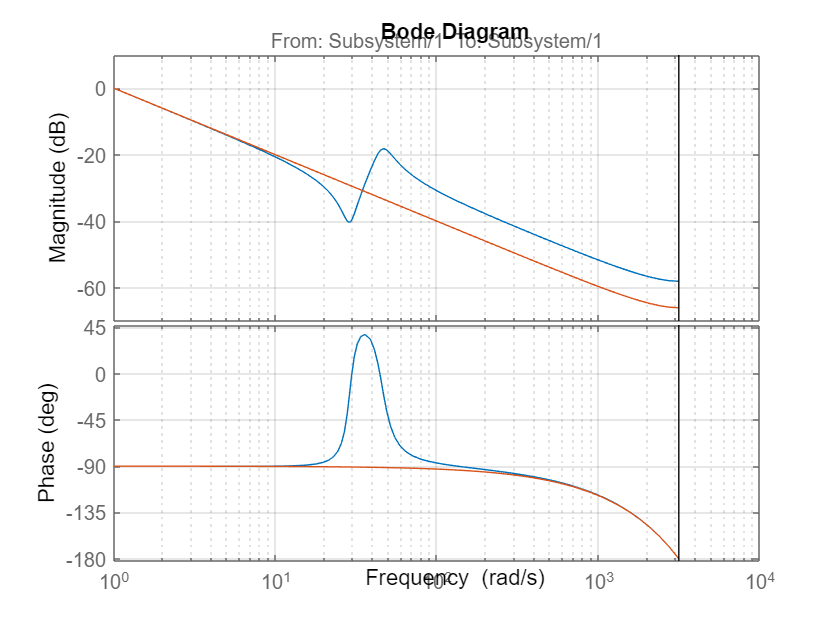

bode(P,Papprox)
grid on

omegaF=15; % per la taratura, scelgo di piazzare i poli in 15 rad/s, ma ogni altra taratura che non causa instabilità andrebbe bene
Kp=2*omegaF*J;
Ki=omegaF^2*J;
C=Kp+Ki/s;
C=c2d(C,dt);

## Progetto del segnale eccitante

uso un chirp fra $\omega_0$ e $\omega_1$ distribuito logaritmicamente, con un esperimento di durata $T_{end}$.

Tend=10;
t=(0:dt:Tend)';

w0=0.5;
w1=300;


r=zeros(length(t),1);
uE=chirp(t,w0/2/pi,Tend,w1/2/pi,'logarithmic');

Posso attivare o disattivare il rumore nella simulazione

use_noise=true;
if (use_noise)
    n_std=0.01;
else
    n_std=0;
end
n=n_std*randn(length(t),1);

eseguo la simulazione

simOut=sim('close_loop_identification.slx',[0 Tend],'',[t r uE n]);

Simulink ha un solutore a passo variabile, ricampiono le uscite con il tempo equispaziato $t$

y_timeseries=simOut.yout{1}.Values.resample(t);
y=y_timeseries.Data;

u_timeseries=simOut.yout{2}.Values.resample(t);
u=u_timeseries.Data;

uC_timeseries=simOut.yout{3}.Values.resample(t);
uC=uC_timeseries.Data;

a_timeseries=simOut.yout{4}.Values.resample(t);
a=a_timeseries.Data;


Grafico l'andamento dell'uscita e dell'azione di controllo

layout=tiledlayout(2,1);

Il primo grafico è l'andamento dell'uscita.

nexttile
plot(t,y)
xlabel('t')
ylabel('y')
grid on

Il secondo grafico è l'andamento dell'azione di controllo.

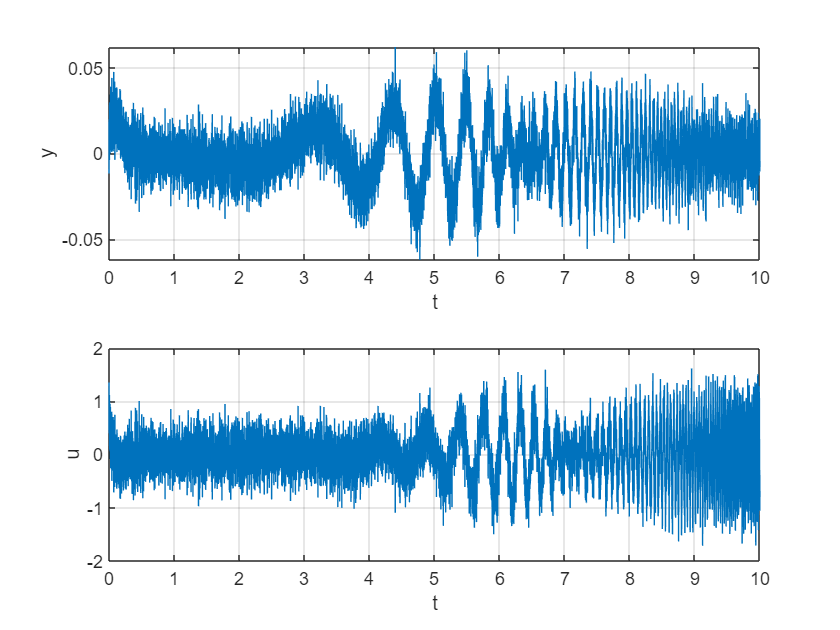

nexttile
plot(t,u)
xlabel('t')
ylabel('u')
grid on

## Calcolo della risposta in frequenza sperimentale

costruisco i dati di identificazione

identification=iddata(y,u,dt);

calcolo la risposta in frequenza

identification_fr=spafdr(identification);

Disegno il diagramma di Bode del sistema

figure
bodeplot(P);
hold on
grid on

e plotto il diagramma di bode sperimentale con intervallo di confidenza $\pm 3$ volte la deviazione standard

bode_line=bodeplot(identification_fr);
showConfidence(bode_line,3)

Le linee verticali tratteggiate rappresentano $\omega_0$ e $\omega_1$, cioè il range di frequenza in cui ho inniettato segnale eccitante.

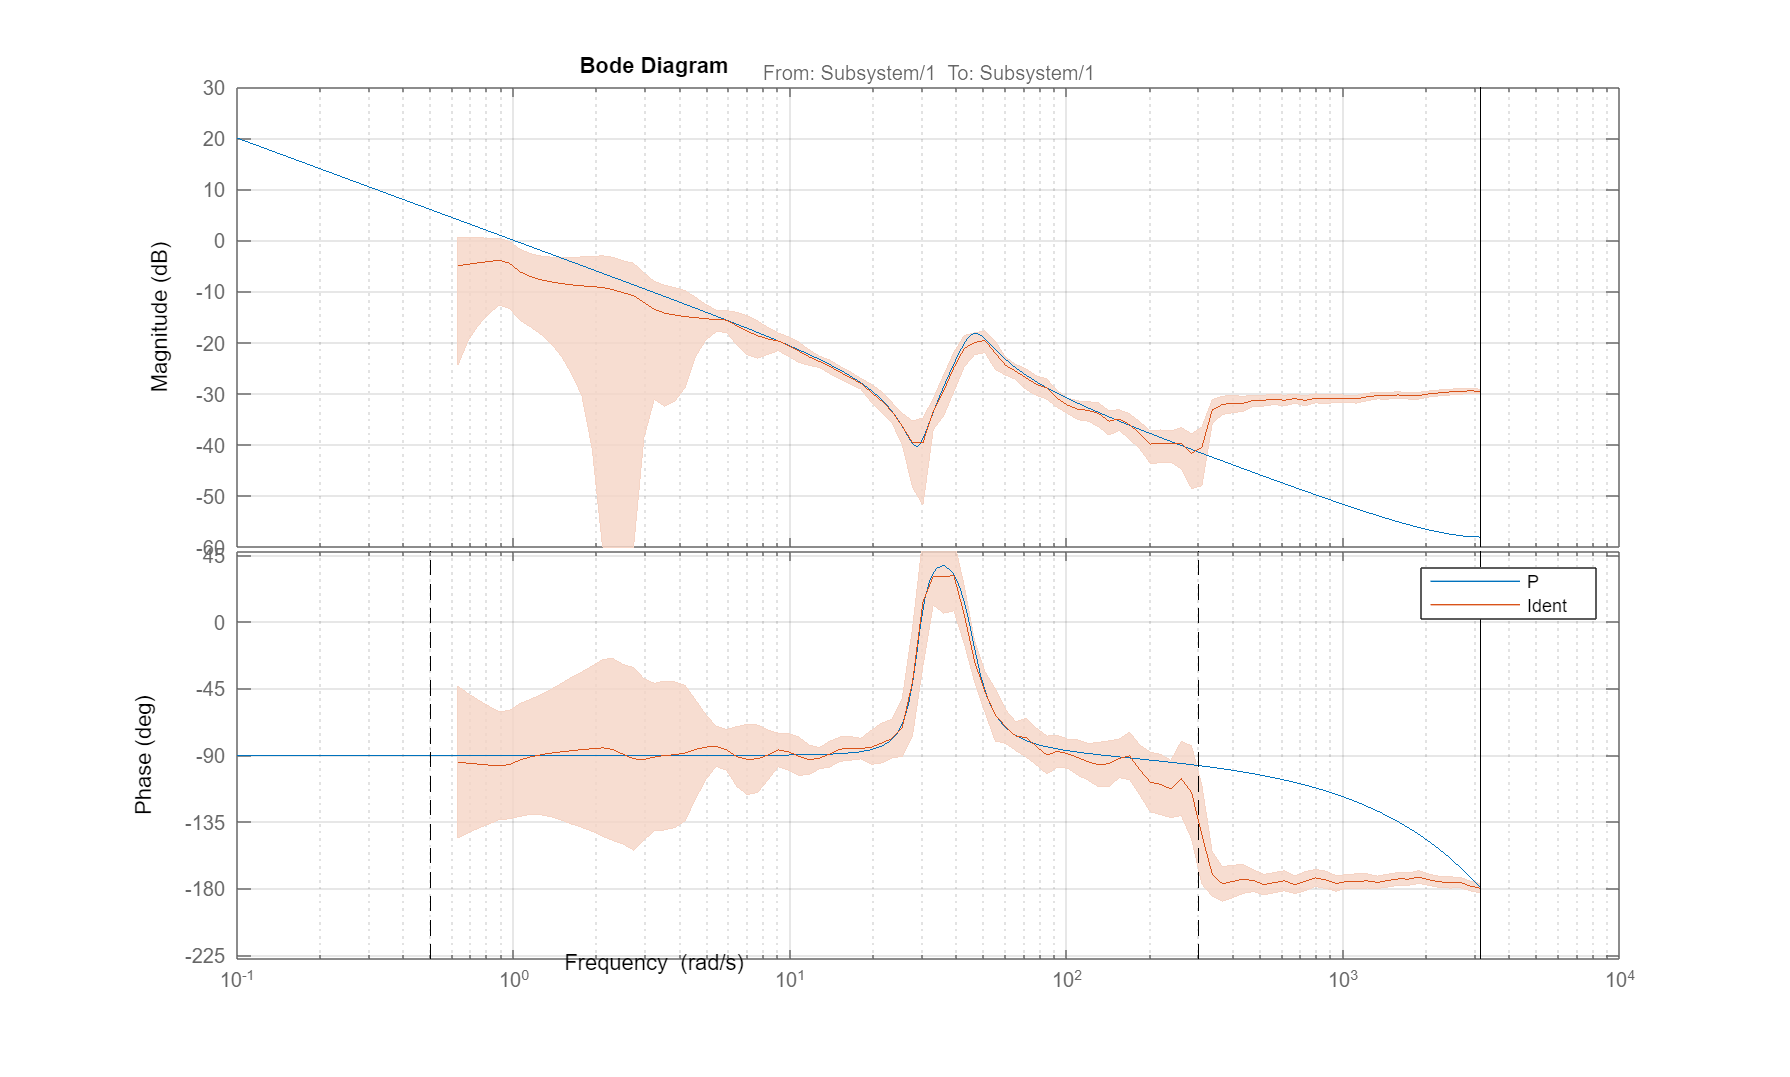

plot([w0 w0],ylim,'--k')
plot([w1 w1],ylim,'--k')

legend('P','Ident')

## Progetto del segnale eccitante più fitto nelle zone di interesse

sommo al chirp, un altro segnale con frequenze [$\omega_{0,b}$ , $\omega_{1,b}$] concentrate nella zona della risonanza e antirisonanza.

w0b=20;
w1b=100;


r=zeros(length(t),1);
uE=chirp(t,w0/2/pi,Tend,w1/2/pi,'logarithmic',90)+...
    chirp(t,w0b/2/pi,Tend,w1b/2/pi,'logarithmic',90); % metto una fase di 90° per iniziare come un seno

eseguo la simulazione

simOut=sim('close_loop_identification.slx',[0 Tend],'',[t r uE n]);

Simulink ha un solutore a passo variabile, ricampiono le uscite con il tempo equispaziato $t$

y_timeseries=simOut.yout{1}.Values.resample(t);
y=y_timeseries.Data;

u_timeseries=simOut.yout{2}.Values.resample(t);
u=u_timeseries.Data;

uC_timeseries=simOut.yout{3}.Values.resample(t);
uC=uC_timeseries.Data;

a_timeseries=simOut.yout{4}.Values.resample(t);
a=a_timeseries.Data;


Grafico l'andamento dell'uscita e dell'azione di controllo

layout=tiledlayout(2,1);

Il primo grafico è l'andamento dell'uscita.

nexttile
plot(t,y)
xlabel('t')
ylabel('y')
grid on

Il secondo grafico è l'andamento dell'azione di controllo.

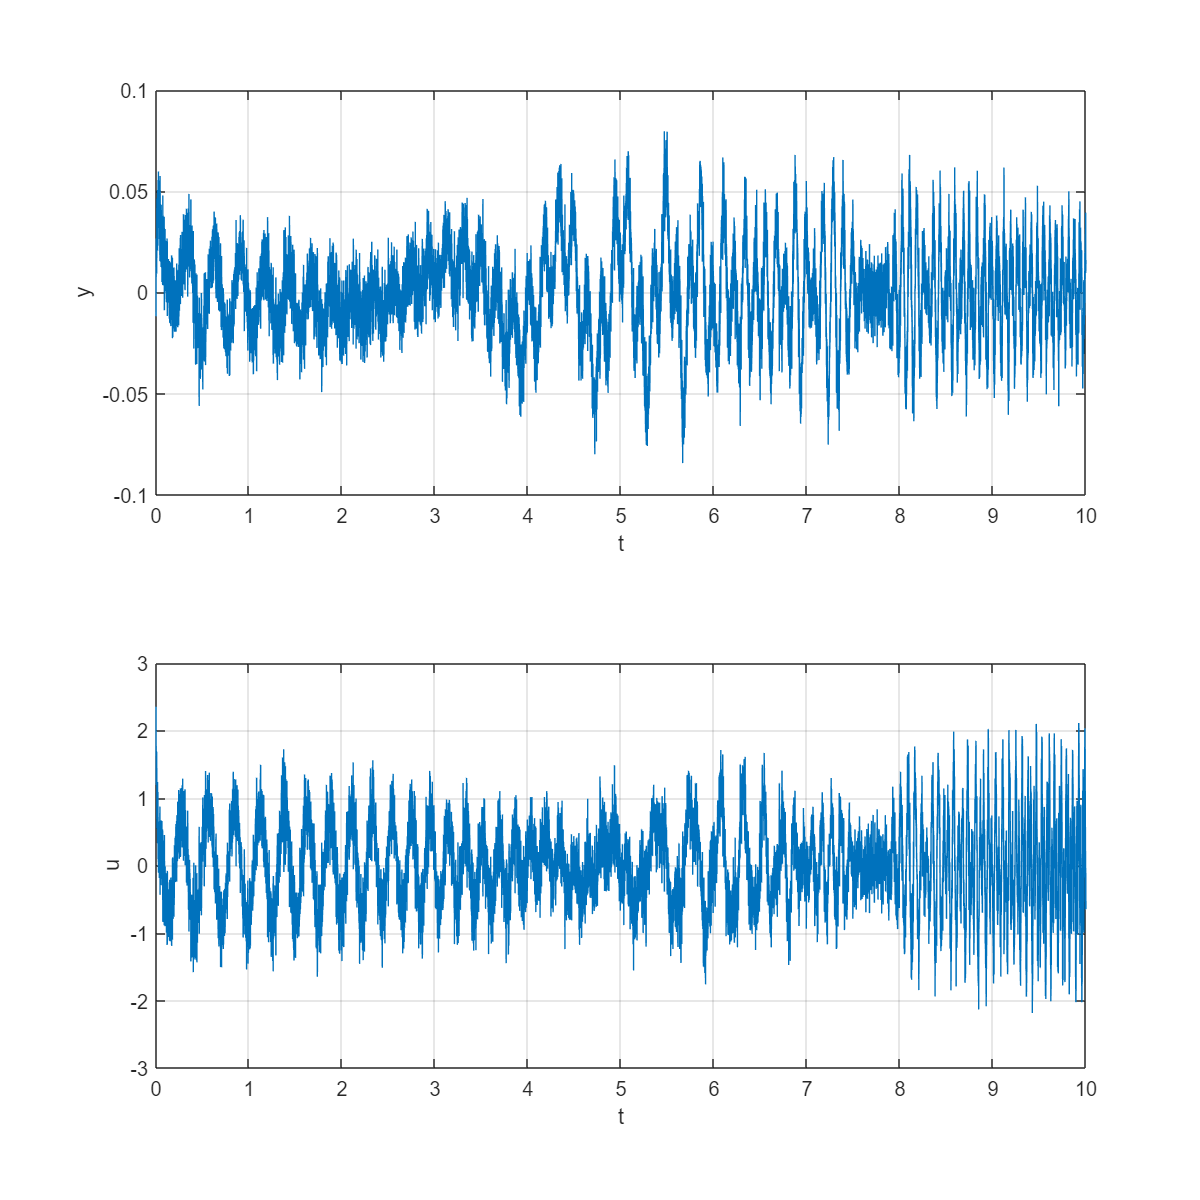

nexttile
plot(t,u)
xlabel('t')
ylabel('u')
grid on

## Calcolo della risposta in frequenza sperimentale

costruisco i dati di identificazione

identification2=iddata(y,u,dt);

calcolo la risposta in frequenza

identification2_fr=spafdr(identification2);

Disegno il diagramma di Bode del sistema

figure
bodeplot(P);
hold on
grid on

e plotto il diagramma di bode sperimentale con intervallo di confidenza $\pm 3$ volte la deviazione standard

bode_line=bodeplot(identification_fr);
showConfidence(bode_line,3)

bode_line2=bodeplot(identification2_fr);
showConfidence(bode_line2,3)

Le linee verticali nere tratteggiate rappresentano $\omega_0$ e $\omega_1$, cioè il range di frequenza in cui ho inniettato segnale eccitante.

Le linee verticali rosse tratteggiate rappresentano $\omega_{0,b}$ e $\omega_{1,b}$, cioè il range di frequenza in cui ho inniettato segnale eccitante.

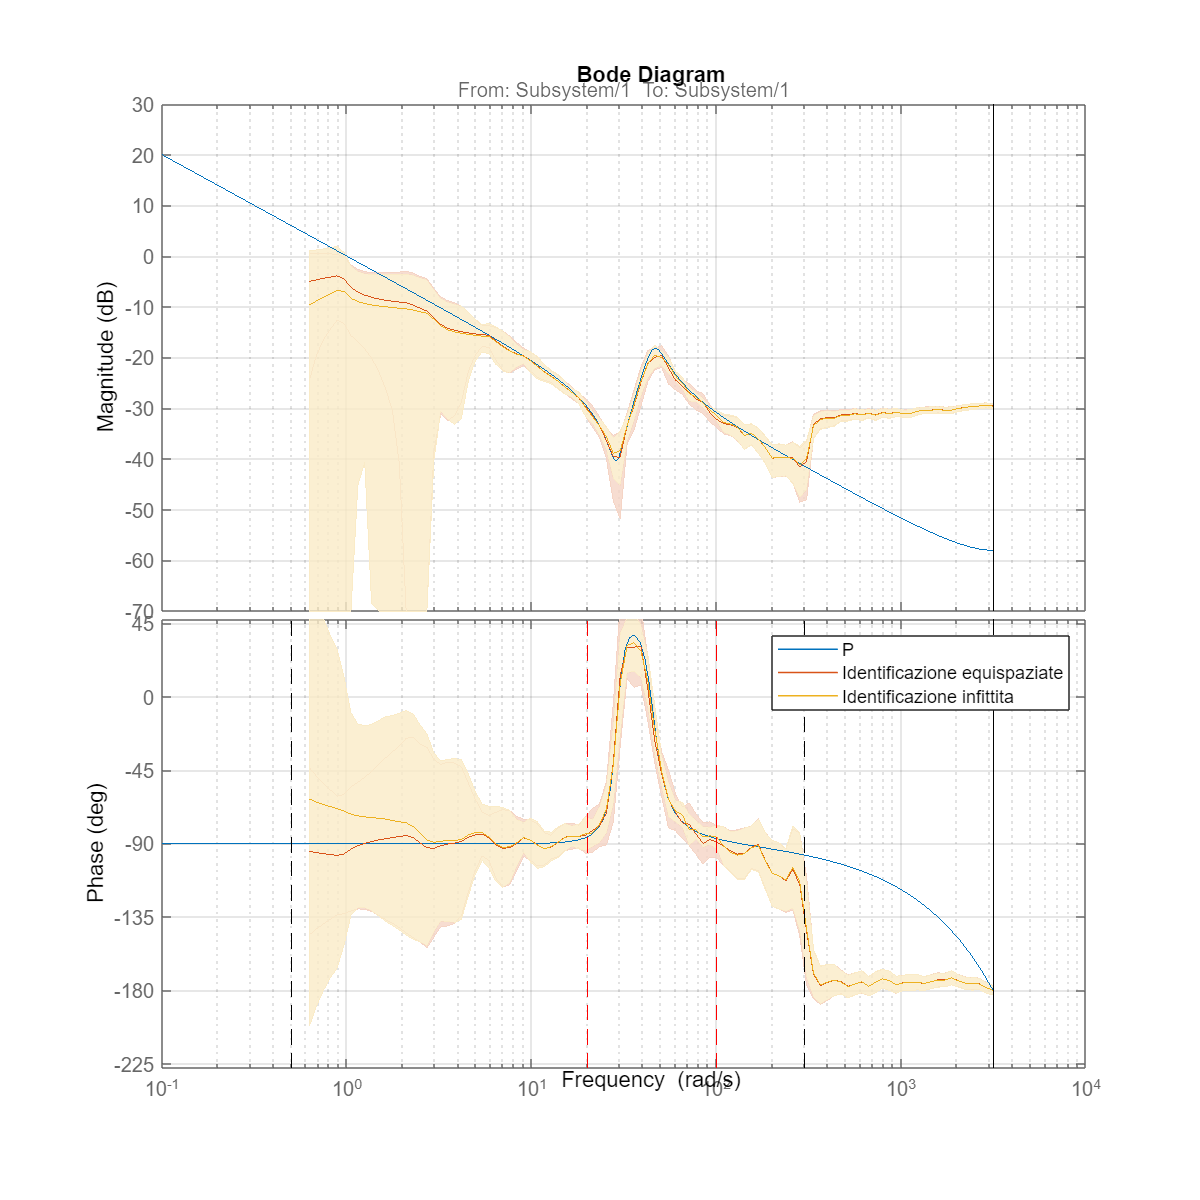

plot([w0 w0],ylim,'--k')
plot([w1 w1],ylim,'--k')
plot([w0b w0b],ylim,'--r')
plot([w1b w1b],ylim,'--r')

legend('P','Identificazione equispaziate','Identificazione infittita')

## Progetto del segnale eccitante solo nelle zone di interesse

uso un chirp solo  con frequenze [$\omega_{0,b}$ , $\omega_{1,b}$] concentrate nella zona della risonanza e antirisonanza.

r=zeros(length(t),1);
uE=chirp(t,w0b/2/pi,Tend,w1b/2/pi,'logarithmic',90); % metto una fase di 90° per iniziare come un seno

eseguo la simulazione

simOut=sim('close_loop_identification.slx',[0 Tend],'',[t r uE n]);

Simulink ha un solutore a passo variabile, ricampiono le uscite con il tempo equispaziato $t$

y_timeseries=simOut.yout{1}.Values.resample(t);
y=y_timeseries.Data;

u_timeseries=simOut.yout{2}.Values.resample(t);
u=u_timeseries.Data;

uC_timeseries=simOut.yout{3}.Values.resample(t);
uC=uC_timeseries.Data;

a_timeseries=simOut.yout{4}.Values.resample(t);
a=a_timeseries.Data;


Grafico l'andamento dell'uscita e dell'azione di controllo

layout=tiledlayout(2,1);

Il primo grafico è l'andamento dell'uscita.

nexttile
plot(t,y)
xlabel('t')
ylabel('y')
grid on

Il secondo grafico è l'andamento dell'azione di controllo.

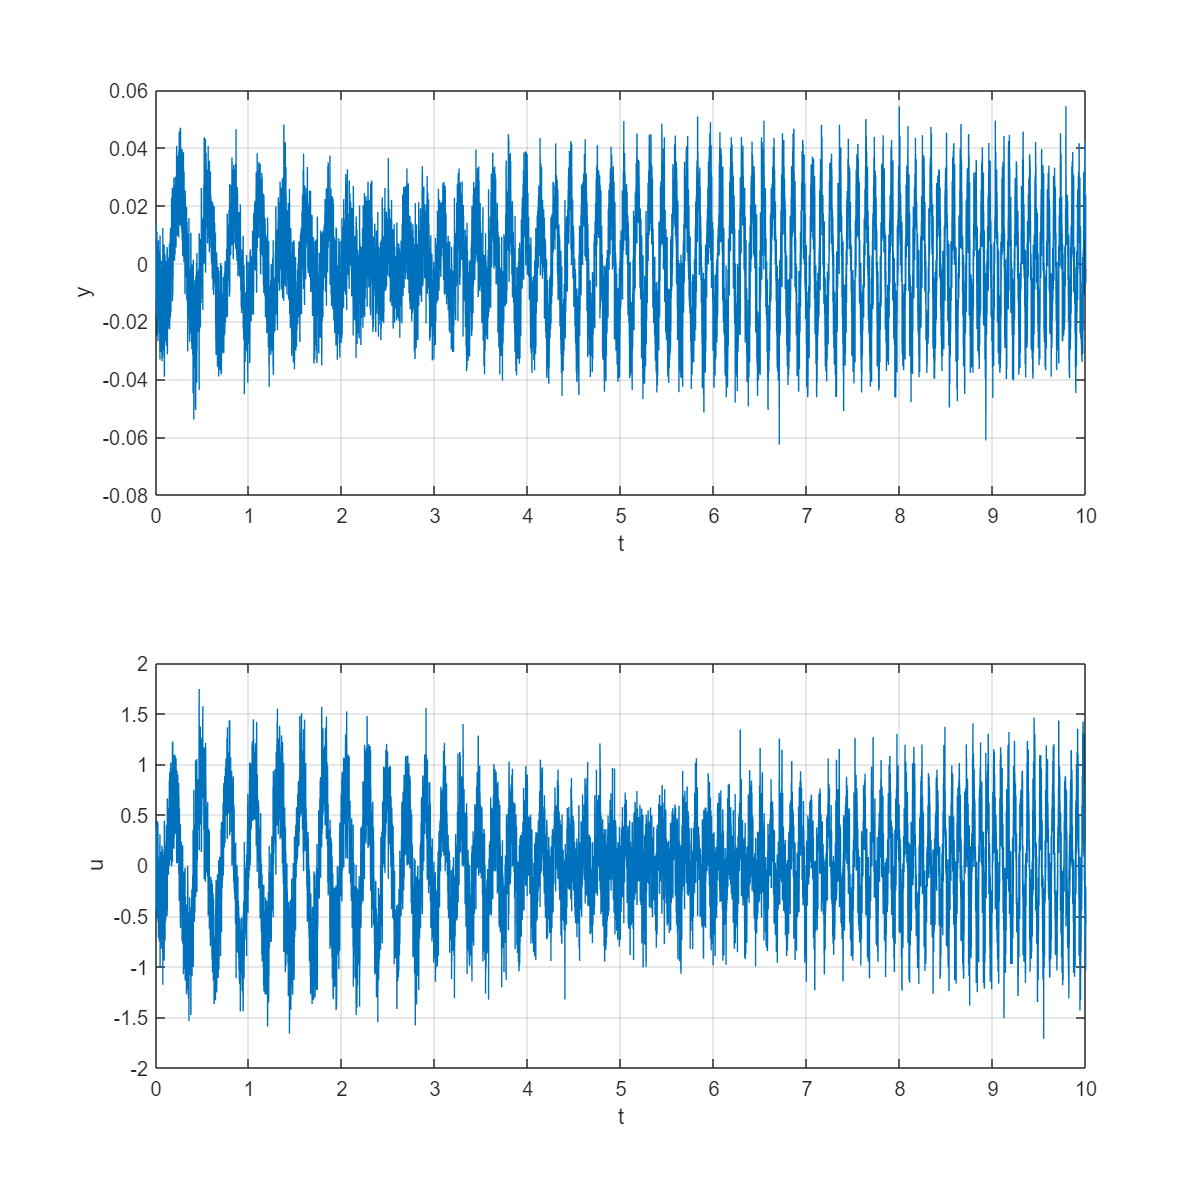

nexttile
plot(t,u)
xlabel('t')
ylabel('u')
grid on

## Calcolo della risposta in frequenza sperimentale

costruisco i dati di identificazione

identification3=iddata(y,u,dt);

calcolo la risposta in frequenza

identification3_fr=spafdr(identification3);

Disegno il diagramma di Bode del sistema

figure
bodeplot(P);
hold on
grid on

e plotto il diagramma di bode sperimentale con intervallo di confidenza $\pm 3$ volte la deviazione standard

bode_line=bodeplot(identification_fr);
showConfidence(bode_line,3)

bode_line3=bodeplot(identification3_fr);
showConfidence(bode_line3,3)

Le linee verticali nere tratteggiate rappresentano $\omega_0$ e $\omega_1$, cioè il range di frequenza in cui ho inniettato segnale eccitante.

Le linee verticali rosse tratteggiate rappresentano $\omega_{0,b}$ e $\omega_{1,b}$, cioè il range di frequenza in cui ho inniettato segnale eccitante.

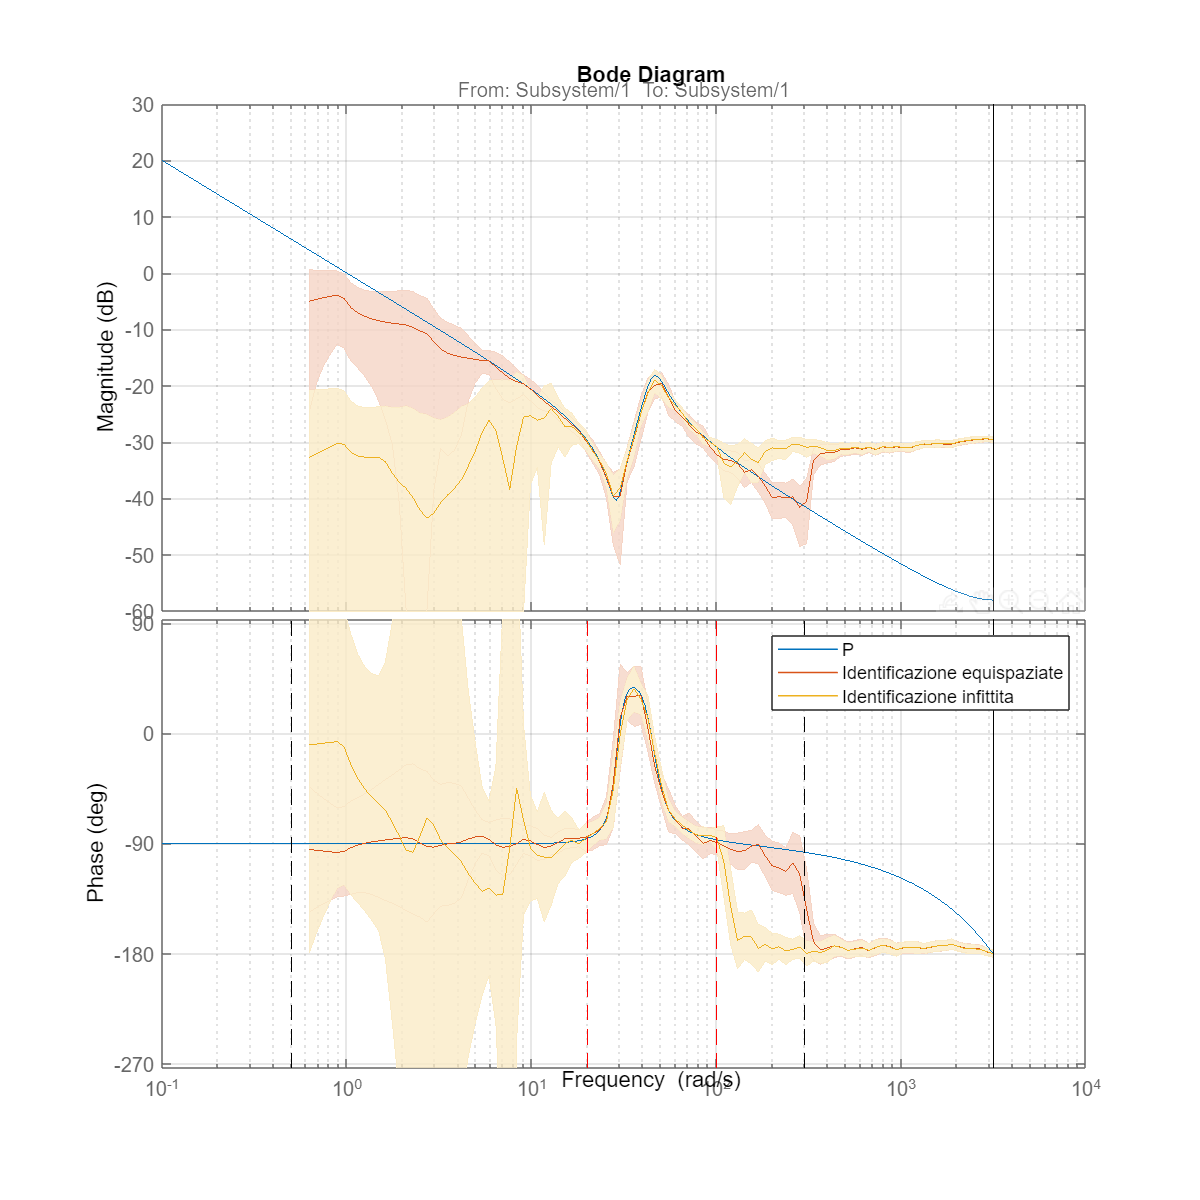

plot([w0 w0],ylim,'--k')
plot([w1 w1],ylim,'--k')
plot([w0b w0b],ylim,'--r')
plot([w1b w1b],ylim,'--r')

legend('P','Identificazione equispaziate','Identificazione infittita')